clear all;clc
img =imread('shapes3.png');
img = im2double(rgb2gray(img));
% img = ones(10,10);
% img(3:6, 4:7) = zeros(4,4);
kernel = buildkernel(5,15,img);
y = fftshift(real(ifft2(fft2(img).*fft2(kernel))));
[B,h,K] = getBm(kernel);
[C,m,S,N,C_haar] = getCh(y);
y= y(:);
L = length(y);

[m_recover, h_recover,X] = mydeconv(y(:),length(y(:)),K,N,C,B);

 
Calling SDPT3 4.0: 33412 variables, 382 equality constraints
------------------------------------------------------------

 num. of constraints = 382
 dim. of sdp    var  = 258,   num. of sdp  blk  =  1
 dim. of linear var  =  1
 checkdepconstr: AAt is not pos. def.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.0e+00|1.0e+03|1.4e+07| 1.181133e+04  0.000000e+00| 0:0:11| chol  1  1 
 1|1.000|0.990|4.6e-12|1.1e+01|1.5e+05| 1.173972e+04  1.909194e-03| 0:0:12| chol  1  1 
 2|1.000|1.000|8.3e-12|9.0e-02|1.1e+04| 9.718166e+03  1.022287e-03| 0:0:18| chol  2  2 
 3|0.991|1.000|4.4e-11|2.7e-02|1.3e+02| 1.291135e+02  2.

C_recover = C*m_recover.*(-1);
x_dec = waverec2(C_recover, S, 'haar');

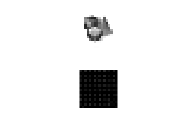

subplot(211)
imshow(img)
subplot(212)
imshow(x_dec)

function kernel = buildkernel(len,theta,img)
    k = fspecial('motion', len,theta);
    [wk,hk] = size(k);
    [wx,hx] = size(img);
    kernel = zeros(wx,hx); 
    kernel(wx/2-(wk+1)/2+1:wx/2+(wk+1)/2-1, hx/2-(hk+1)/2+1:hx/2+(hk+1)/2-1) = k;
end
function [B,h,K] = getBm(kernel)
    kernel = kernel(:);
    K = sum(kernel~=0);
    B = zeros(length(kernel),K);
    idx = 1;
    h = zeros(K,1);
    for i = 1:length(kernel)
        if kernel(i) ~= 0
            B(i,idx) = 1;
            h(idx) = kernel(i);
            idx = idx + 1;            
        end
    end
end
function [C,m,S,N,C_haar] = getCh(img)
    [C_haar,S] =  wavedec2(img, 1, 'haar');
    N = sum(C_haar~= 0);
    img = img(:);
    C = zeros(length(img),N);
    m = zeros(N,1);
    idx = 1;
    for i=1:length(C_haar)
        if C_haar(i) ~= 0
            C(i,idx) = 1;
            m(idx) = C_haar(i);
            idx=idx +1;
        end
    end
end
function [m_recover, h_recover,X] = mydeconv(y,L,K,N,C,B)
    y_hat = dftmtx(L)*y;
    b_hat = dftmtx(L)*B;
    c_hat = dftmtx(L)*C;
    A = [];
    for i= 1:N
        del = diag(sqrt(L)* c_hat(:,i));
        A= [A del*b_hat];
    end
    cvx_begin
        variable X(K,N) 
        minimise( norm_nuc(X) )
        subject to
            A*X(:) == y_hat
    cvx_end
    [u,s,v] = svd(X);
    m_recover = v(:,1);
    h_recover = u(:,1);
end